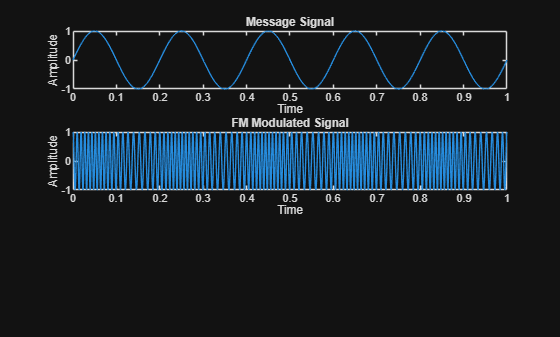

clc;
clear;
close all;

fs = 10000;      % Sampling frequency
t = 0:1/fs:1;    % Time vector

fm = 5;          % Message frequency
fc = 100;        % Carrier frequency
beta = 5;        % Modulation index
m = sin(2*pi*fm*t);
figure;
subplot(3,1,1)
plot(t,m)
title('Message Signal')
xlabel('Time')
ylabel('Amplitude')
c = cos(2*pi*fc*t);
fm_signal = fmmod(m, fc, fs, beta*fm);
subplot(3,1,2)
plot(t,fm_signal)
title('FM Modulated Signal')
xlabel('Time')
ylabel('Amplitude')

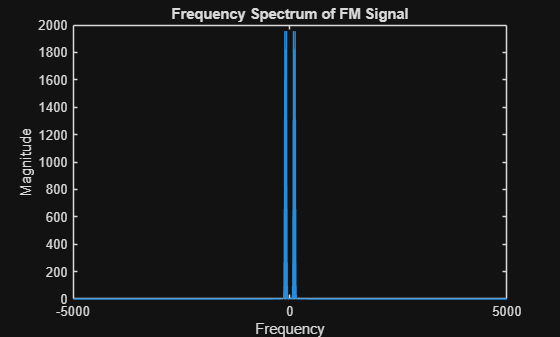

N = length(fm_signal);
f = (-N/2:N/2-1)*(fs/N);
FM = fftshift(fft(fm_signal));

figure;
plot(f,abs(FM))
title('Frequency Spectrum of FM Signal')
xlabel('Frequency')
ylabel('Magnitude')

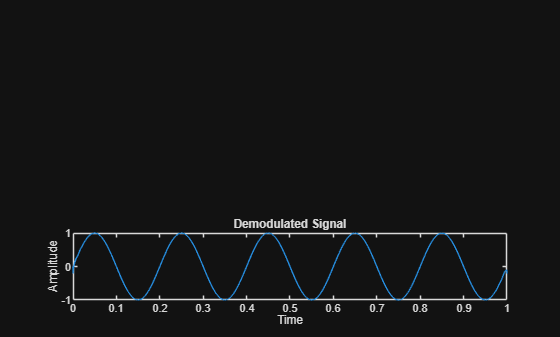

demod = fmdemod(fm_signal, fc, fs, beta*fm);
subplot(3,1,3)
plot(t,demod)
title('Demodulated Signal')
xlabel('Time')
ylabel('Amplitude')